This file runs an iterative search for the optimal solution to a simple 2D moving traveling salesman problem, inspired by [https://stackoverflow.com/questions/15485473/how-can-i-find-the-shortest-path-between-100-moving-targets-live-demo-included](https://stackoverflow.com/questions/15485473/how-can-i-find-the-shortest-path-between-100-moving-targets-live-demo-included)

Set up initial conditions for the problem instance: starting location for the chase vehicle, discrete-time loop paths for each "fish".  

DIM = 10; % Board size
MAX_TIME = 10000; % Initialize time-to-beat
myLoc = [3,5]; % Starting location for the chase vehicle
path1 = [1,1; 2,1; 3,1; 3,2; 3,3; 2,3; 1,3; 1,2]; % Paths each represent one fish's loop
path2 = [4,2; 4,3; 4,4; 4,5; 5,5; 5,4; 5,3; 5,2];
path3 = [8,8; 8,9; 9,9; 9,8; 9,7; 9,6; 8,6; 7,6; 7,7; 7,8];
fish = {path1, path2, path3};
% Longer demo with more fish - uncomment these two lines
path4 = [1,1; 1,2; 1,3; 1,4; 1,5; 1,6; 1,7; 1,6; 1,5; 2,5; 3,5; 4,5; 4,4; 4,3; 3,3; 3,2; 2,2; 2,1];
fish = {path1, path2, path3, path4};

Set up variables for the demo:

ans =      4     3     2     1


myTrack =      3     5
     1     4
     9     7
     5     5
     3     1


steps =      1     4    15    21    27


ans =      4     3     1     2


myTrack =      3     5
     1     4
     9     7
     3     1
     5     3


steps =      1     4    15    27    31


ans =      4     2     3     1


myTrack =      3     5
     1     4
     4     2
     8     6
     3     1


steps =      1     4     9    17    27


ans =      4     2     1     3


myTrack =      3     5
     1     4
     4     2
     3     1
     9     8


steps =      1     4     9    11    24


ans =      4     1     3     2


myTrack =      3     5
     1     4
     2     3
     9     6
     5     5


steps =      1     4     6    16    21


ans =      4     1     2     3


myTrack =      3     5
     1     4
     2     3
     4     2
     8     6


steps =      1     4     6     9    17


ans =      3     4     2     1


myTrack =      3     5
     8     6
     4     5
     4     5
     2     1


steps =      1     7    12    12    18


ans =      3     4     1     2


myTrack =      3     5
     8     6
     4     5
     2     1
     5     3


steps =      1     7    12    18    23


ans =      3     2     4     1


myTrack =      3     5
     8     6
     4     5
     4     5
     2     1


steps =      1     7    12    12    18


ans =      3     2     1     4


myTrack =      3     5
     8     6
     4     5
     2     1
     2     1


steps =      1     7    12    18    18


ans =      3     1     4     2


myTrack =      3     5
     8     6
     2     1
     2     1
     5     3


steps =      1     7    18    18    23


ans =      3     1     2     4


myTrack =      3     5
     8     6
     2     1
     5     3
     2     5


steps =      1     7    18    23    28


ans =      2     4     3     1


myTrack =      3     5
     4     4
     1     6
     9     6
     3     1


steps =      1     3     8    16    27


ans =      2     4     1     3


myTrack =      3     5
     4     4
     1     6
     3     3
     9     8


steps =      1     3     8    13    24


ans =      2     3     4     1


myTrack =      3     5
     4     4
     7     6
     4     5
     2     1


steps =      1     3     8    12    18


ans =      2     3     1     4


myTrack =      3     5
     4     4
     7     6
     2     1
     2     1


steps =      1     3     8    18    18


ans =      2     1     4     3


myTrack =      3     5
     4     4
     3     3
     1     5
     8     6


steps = 1×5
     1     3     5     9    17


ans = 1×4
     2     1     3     4


myTrack = 5×2
     3     5
     4     4
     3     3
     9     7
     1     6


steps = 1×5
     1     3     5    15    24


ans = 1×4
     1     4     3     2


myTrack = 5×2
     3     5
     3     2
     1     5
     8     6
     5     5


steps = 1×5
     1     4     9    17    21


ans = 1×4
     1     4     2     3


myTrack = 5×2
     3     5
     3     2
     1     5
     4     5
     8     6


steps = 1×5
     1     4     9    12    17


ans = 1×4
     1     3     4     2


myTrack = 5×2
     3     5
     3     2
     9     7
     1     6
     4     5


steps = 1×5
     1     4    15    24    28


ans = 1×4
     1     3     2     4


myTrack = 5×2
     3     5
     3     2
     9     7
     5     5
     1     6


steps = 1×5
     1     4    15    21    26


ans = 1×4
     1     2     4     3


myTrack = 5×2
     3     5
     3     2
     5     3
     3     5
     8     6


steps = 1×5
     1     4     7    11    17


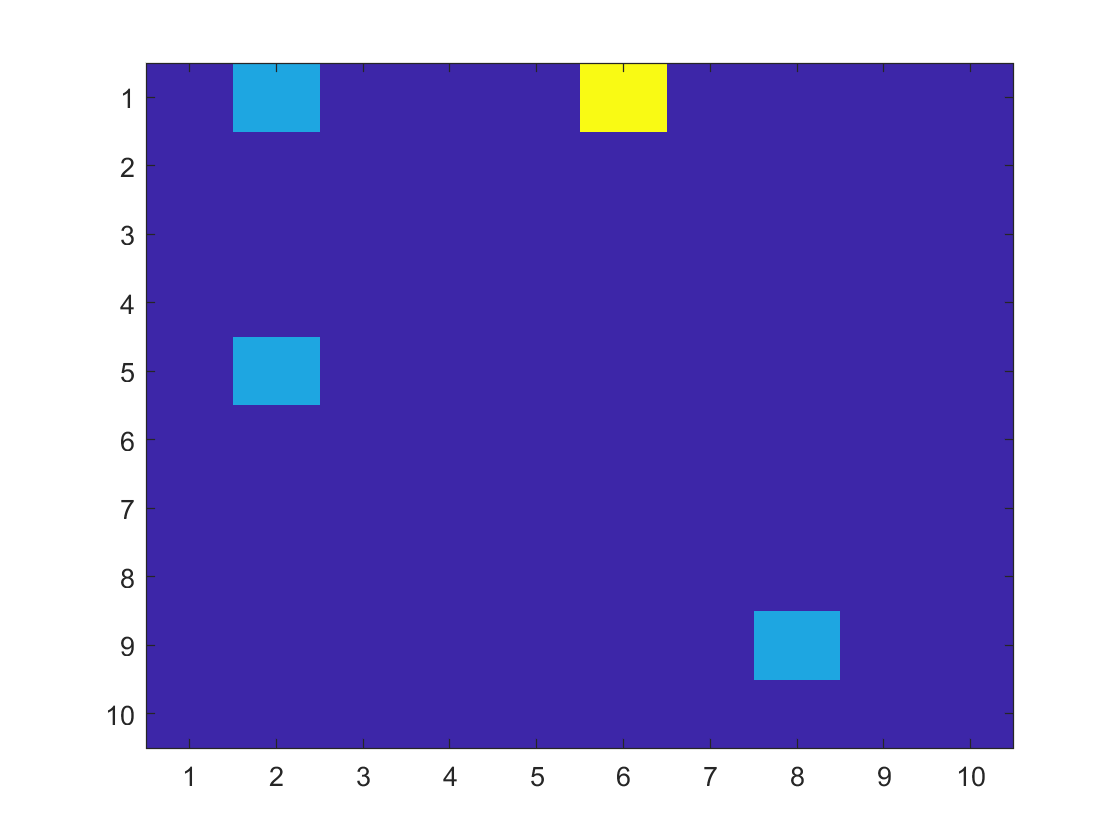

ans = 1×4
     1     2     3     4


myTrack = 5×2
     3     5
     3     2
     5     3
     9     7
     1     6


steps = 1×5
     1     4     7    15    24


myTrack = zeros(size(fish,2)+1,2);
myTrack(1,:)=myLoc;
steps = ones(1,size(fish,2)+1);
sequence = 1:size(fish,2);
permutations = perms(sequence); % This allows us to loop through all possible pursuit sequences
bestTrack = myTrack; % Initialize variables to store the best sequence found so far
bestSteps = steps;
bestSteps(size(fish,2)+1) = MAX_TIME;
% Loop through all sequences
for jx=1:size(permutations,1)
    % Get time and location of each fish intercept in the given sequence
    for ix=1:size(fish,2)
        [time, loc] = fishIntercept(permutations(jx,ix), myTrack(ix,:), steps(ix), fish);
        steps(ix+1) = time;
        myTrack(ix+1,:)=loc;
    end
    % Draw the board for visualization (comment this loop out to speed up
    % the program)
    for round=1:size(fish,2)
        for timer=steps(round):steps(round+1)-1
            drawBoard(timer, myTrack(round,:), fish, DIM)
            pause(0.2) % Increase this to slow down the animation
        end
        drawBoard(steps(size(fish,2)+1),myTrack(size(fish,2)+1,:), fish, DIM)
        pause(0.2)
    end
    % Comment out the next three lines to skip printing data for each
    % sequence
    permutations(jx,:)
    myTrack
    steps
    if steps(size(fish,2)+1) < bestSteps(size(fish,2)+1)
        bestSteps = steps;
        bestTrack = myTrack;
        sequence = permutations (jx,:);
    end
end

Intercept locations and times:

bestTrack

bestTrack = 5×2
     3     5
     1     4
     2     3
     4     2
     8     6


bestSteps

bestSteps = 1×5
     1     4     6     9    17


sequence

sequence = 1×4
     4     1     2     3


Given a time-step, location of the chase vehicle, the fish paths, and the board dimension, draw the current state.

function drawBoard(time, myTrack, allFish, DIM)
    board = zeros(DIM);
    for ix=1:size(allFish,2)
        loc = fishLocation(ix,time,allFish);
        board(loc(1),loc(2)) = 100;
    end
    board(myTrack(1),myTrack(2)) = board(myTrack(1),myTrack(2))+200;
    image(board)
end

Find the location and time of intercept for the shortest path to a fish, given the current time and the location of the chase vehicle.

function [time, fishLoc] = fishIntercept(fishNum, currLoc, currTime, allFish)
    time = currTime;
    fishLoc = fishLocation(fishNum, time, allFish);
    while (pdist2(fishLoc,currLoc,'cityblock')~= (time-currTime))
        time = time + 1;
        fishLoc = fishLocation(fishNum, time, allFish);
    end
end

Get the location of a particular fish at a time-step.

function loc = fishLocation(fishNum, time, allFish)
    fish = allFish{fishNum};
    sz = size(fish,1);
    ix = mod(time, sz);
    if ix == 0 
        ix = sz;
    end
    loc = fish(ix,:);
end